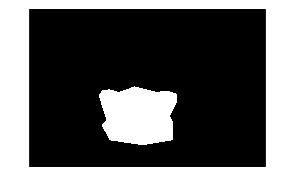

close('all');   % close all open figures so we start with a clean slate!

im_bg = im2double(imread('C:/Users/Zack/Pictures/swim.jpg'));        % background image
im_obj = im2double(imread('C:/Users/Zack/Pictures/bear.jpg'));       % source image

% Get source region mask (extracted object) from the user
% First draw a polygon on the source image for applying the mask

% [poly_x, poly_y] = getPolygonForMask(im_obj);

% NOTE: For your own image sets, simply uncomment the call to getPolygonForMask(), and
% DO NOT USE the hard-coded polygon coordinates below!
poly_x = [276.4628  324.9961  391.5884  425.4488  453.6659  457.0519  433.3496 442.3791 ...
    441.2504  348.6984  248.2457  222.2860  238.0876  226.8008  222.2860  214.3853  224.5434  248.2457];
poly_y = [255.3512  238.4209  255.3512  250.8364  260.9946  283.5682  329.8442  349.0318 ...
    404.3372  419.0101  404.3372  356.9326  342.2597  308.3992  292.5977  265.5093  250.8364  247.4504];

% Convert polygon to a binary mask
objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
imshow(objmask)


% Next, align the source object (im_s) and mask (mask_s) with the background image.  
% Get the bottom center location on the target image by using the function
% getBottomCenterLoc interactively

% [center_x, bottom_y] = getBottomCenterLoc(im_bg);

% NOTE: For your own image sets, simply uncomment the call to getBottomCenterLoc(), and
% DO NOT USE the hard-coded alignment coordinates below!
center_x = 575.9264;
bottom_y = 432.4922;

% Translate both the source image and the object mask for proper alignment
% w.r.t. the background image
% Pad the extracted object by 64 pixels each side to allow for feathering/blending overlap.

padding = 64;
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);  % convert mask from binary to double

% Call the function to blend the images using the mask
levels = 6;         % levels in the Laplacian pyramid
result1 = laplacian_blend(im_bg, im_s, mask_s, levels);

ans =    433   650     3


ans =          866        1300           3


ans =    217   325     3


ans =    433   650     3


ans =    109   163     3


ans =    217   325     3


ans =     55    82     3


ans =    109   163     3


ans =     28    41     3


ans =     55    82     3


ans =     28    41     3


pyr_size =     55    82     3


ans =     55    82     3


pyr_size =    109   163     3


ans =    109   163     3


pyr_size =    217   325     3


ans =    217   325     3


pyr_size =    433   650     3


ans =    433   650     3


pyr_size =          866        1300           3


ans =    433   650     3


ans =          866        1300           3


ans =    217   325     3


ans =    433   650     3


ans =    109   163     3


ans =    217   325     3


ans =     55    82     3


ans =    109   163     3


ans =     28    41     3


ans =     55    82     3


ans =     28    41     3


pyr_size =     55    82     3


ans =     55    82     3


pyr_size =    109   163     3


ans =    109   163     3


pyr_size =    217   325     3


ans =    217   325     3


pyr_size =    433   650     3


ans =    433   650     3


pyr_size =          866        1300           3


ans =    433   650


ans =          866        1300


ans =    217   325


ans =    433   650


ans =    109   163


ans =    217   325


ans =     55    82


ans =    109   163


ans =     28    41


ans =     55    82


ans = 1×3
         866        1300           3


ans = 1×2
         866        1300


ans = 1×3
   433   650     3


ans = 1×2
   433   650


ans = 1×3
   217   325     3


ans = 1×2
   217   325


ans = 1×3
   109   163     3


ans = 1×2
   109   163


ans = 1×3
    55    82     3


ans = 1×2
    55    82


ans = 1×3
    28    41     3


ans = 1×2
    28    41


imsize = 1×3
         866        1300           3


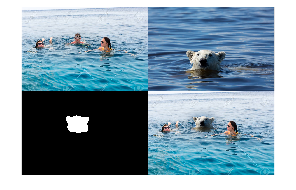


% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result1});



%%
% -------------------------------------------------------------------------
% IMPORTANT NOTE (please read carefully)
% -------------------------------------------------------------------------
% Repeat your method for 4 more sets of images.  But remember that for
% these you must interactively specify the mask and alignment ONE TIME.
%
% The Matlab Grader website does not allow interactive code.  Therefore,
% you must first develop and run your code either in the Matlab computer
% app, or in the full Matlab Online version (https://matlab.mathworks.com).
% Both of those version allow interactive code, which will allow you to
% specify a mask for object selection and an alignment point in the
% target/background image.
%
% Once you are satisfied with your choice of mask and alignment, copy the
% values of the poly_x and poly_y vectors (which define the vertices of the
% polygon mask), and the values of center_x and bottom_y (which specify the
% alignment) from the output of the Command Window.  Then, hard-code these
% values into your code below, just like it was done for the first image
% set above.
%
% There are two reasons for hard-coding these values.  First, it avoids the
% need to repeatedly interact with the tool to specify the mask and
% alignment while you are fine tuning the blending algorithm.  Second, you
% will be submitting your final work on the Matlab Grader website which
% does not allow interactive code.
%
% -------------------------------------------------------------------------

%%%%% your own images
im_bg = im2double(imread('https://giantveggiegardener.files.wordpress.com/2013/01/orange-conventional.jpg?w=584'));        % background image
im_obj = im2double(imread('https://target.scene7.com/is/image/Target/GUEST_14ef7290-1621-47e0-8c52-1f604be1c022?wid=488&hei=488&fmt=pjpeg'));       % source image

% % Get source region mask (extracted object) from the user
% %  First draw a polygon on the source image for applying the mask

%[poly_x, poly_y] = getPolygonForMask(im_obj);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


poly_x = [212.4883  290.7391  215.3338  166.9606  127.1239   94.4009   80.1735   87.2872  102.9373  131.3921  172.6516];       % display x coords of polygon
poly_y = [382.5058  110.7624   95.1122  100.8032  123.5671  163.4038  200.3950  261.5729  311.3688  351.2055  379.6603];       % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.

objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
 
% % Get the bottom center location on the target image by using the function
% % getBottomCenterLoc interactively

%[center_x, bottom_y] = getBottomCenterLoc(im_bg);
disp("Copy the values of center_x and bottom_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of center_x and bottom_y from the Command Window below and hard code them inside your code for submission via the Grader website.


center_x = 146.2373;       % display x coord where center of object should be placed
bottom_y = 332.1613;       % display y coord where bottom of object should be placed
% Once you have these coordinates, comment out the call to getBottomCenterLoc()
% and hard code the coordinates instead.

padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result2 = laplacian_blend(im_bg, im_s, mask_s, levels);

ans = 1×3
   187   250     3


ans = 1×3
   373   500     3


ans = 1×3
    94   125     3


ans = 1×3
   187   250     3


ans = 1×3
    47    63     3


ans = 1×3
    94   125     3


ans = 1×3
    24    32     3


ans = 1×3
    47    63     3


ans = 1×3
    12    16     3


ans = 1×3
    24    32     3


ans = 1×3
    12    16     3


pyr_size = 1×3
    24    32     3


ans = 1×3
    24    32     3


pyr_size = 1×3
    47    63     3


ans = 1×3
    47    63     3


pyr_size = 1×3
    94   125     3


ans = 1×3
    94   125     3


pyr_size = 1×3
   187   250     3


ans = 1×3
   187   250     3


pyr_size = 1×3
   373   500     3


ans = 1×3
   187   250     3


ans = 1×3
   373   500     3


ans = 1×3
    94   125     3


ans = 1×3
   187   250     3


ans = 1×3
    47    63     3


ans = 1×3
    94   125     3


ans = 1×3
    24    32     3


ans = 1×3
    47    63     3


ans = 1×3
    12    16     3


ans = 1×3
    24    32     3


ans = 1×3
    12    16     3


pyr_size = 1×3
    24    32     3


ans = 1×3
    24    32     3


pyr_size = 1×3
    47    63     3


ans = 1×3
    47    63     3


pyr_size = 1×3
    94   125     3


ans = 1×3
    94   125     3


pyr_size = 1×3
   187   250     3


ans = 1×3
   187   250     3


pyr_size = 1×3
   373   500     3


ans = 1×2
   187   250


ans = 1×2
   373   500


ans = 1×2
    94   125


ans = 1×2
   187   250


ans = 1×2
    47    63


ans = 1×2
    94   125


ans = 1×2
    24    32


ans = 1×2
    47    63


ans = 1×2
    12    16


ans = 1×2
    24    32


ans = 1×3
   373   500     3


ans = 1×2
   373   500


ans = 1×3
   187   250     3


ans = 1×2
   187   250


ans = 1×3
    94   125     3


ans = 1×2
    94   125


ans = 1×3
    47    63     3


ans = 1×2
    47    63


ans = 1×3
    24    32     3


ans = 1×2
    24    32


ans = 1×3
    12    16     3


ans = 1×2
    12    16


imsize = 1×3
   373   500     3


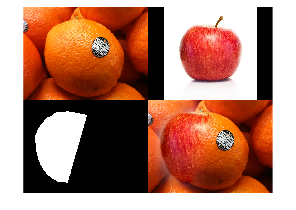


% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result2});



% REPEAT ABOVE FOR IMAGE SET 3
%%%%% your own images
im_bg = im2double(imread('https://www.maxpixel.net/static/photo/1x/Male-Palm-Man-Finger-Woman-Hand-Women-Skin-1701964.jpg'));        % background image
im_obj = im2double(imread('https://ak.picdn.net/shutterstock/videos/14045204/thumb/1.jpg'));       % source image

% % Get source region mask (extracted object) from the user
% %  First draw a polygon on the source image for applying the mask

%[poly_x, poly_y] = getPolygonForMask(im_obj);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


poly_x = [219.3894  176.2005  136.9378  109.4539  119.2696  150.6797  195.8318  280.2465  335.2143  398.0346  447.1129  484.4124  504.0438  482.4493 431.4078  343.0668  264.5415];       % display x coords of polygon
poly_y = [185.5323  207.1267  242.4631  271.9101  297.4309  307.2465  326.8779  352.3986  356.3249  334.7304  305.2834  269.9470  248.3525  216.9424 187.4954  173.7535  165.9009];       % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.

objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
 
% % Get the bottom center location on the target image by using the function
% % getBottomCenterLoc interactively

%[center_x, bottom_y] = getBottomCenterLoc(im_bg);
disp("Copy the values of center_x and bottom_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of center_x and bottom_y from the Command Window below and hard code them inside your code for submission via the Grader website.


center_x = 623.1728;       % display x coord where center of object should be placed
bottom_y = 546.3065;       % display y coord where bottom of object should be placed
% Once you have these coordinates, comment out the call to getBottomCenterLoc()
% and hard code the coordinates instead.

padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result3 = laplacian_blend(im_bg, im_s, mask_s, levels);

ans = 1×3
   360   480     3


ans = 1×3
   720   960     3


ans = 1×3
   180   240     3


ans = 1×3
   360   480     3


ans = 1×3
    90   120     3


ans = 1×3
   180   240     3


ans = 1×3
    45    60     3


ans = 1×3
    90   120     3


ans = 1×3
    23    30     3


ans = 1×3
    45    60     3


ans = 1×3
    23    30     3


pyr_size = 1×3
    45    60     3


ans = 1×3
    45    60     3


pyr_size = 1×3
    90   120     3


ans = 1×3
    90   120     3


pyr_size = 1×3
   180   240     3


ans = 1×3
   180   240     3


pyr_size = 1×3
   360   480     3


ans = 1×3
   360   480     3


pyr_size = 1×3
   720   960     3


ans = 1×3
   360   480     3


ans = 1×3
   720   960     3


ans = 1×3
   180   240     3


ans = 1×3
   360   480     3


ans = 1×3
    90   120     3


ans = 1×3
   180   240     3


ans = 1×3
    45    60     3


ans = 1×3
    90   120     3


ans = 1×3
    23    30     3


ans = 1×3
    45    60     3


ans = 1×3
    23    30     3


pyr_size = 1×3
    45    60     3


ans = 1×3
    45    60     3


pyr_size = 1×3
    90   120     3


ans = 1×3
    90   120     3


pyr_size = 1×3
   180   240     3


ans = 1×3
   180   240     3


pyr_size = 1×3
   360   480     3


ans = 1×3
   360   480     3


pyr_size = 1×3
   720   960     3


ans = 1×2
   360   480


ans = 1×2
   720   960


ans = 1×2
   180   240


ans = 1×2
   360   480


ans = 1×2
    90   120


ans = 1×2
   180   240


ans = 1×2
    45    60


ans = 1×2
    90   120


ans = 1×2
    23    30


ans = 1×2
    45    60


ans = 1×3
   720   960     3


ans = 1×2
   720   960


ans = 1×3
   360   480     3


ans = 1×2
   360   480


ans = 1×3
   180   240     3


ans = 1×2
   180   240


ans = 1×3
    90   120     3


ans = 1×2
    90   120


ans = 1×3
    45    60     3


ans = 1×2
    45    60


ans = 1×3
    23    30     3


ans = 1×2
    23    30


imsize = 1×3
   720   960     3


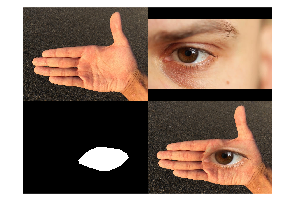


% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result3});




% REPEAT ABOVE FOR IMAGE SET 4
%%%%% your own images
im_bg = im2double(imread('https://artsy-media-uploads.s3.amazonaws.com/2P6t_Yt6dF0TNN76dlp-_Q%2F3417757448_4a6bdf36ce_o.jpg'));        % background image
im_obj = im2double(imread('https://static01.nyt.com/images/2021/06/07/multimedia/07xp-oz-dinosaur-02/07xp-oz-dinosaur-02-articleLarge.jpg?quality=75&auto=webp&disable=upscale'));       % source image

% % Get source region mask (extracted object) from the user
% %  First draw a polygon on the source image for applying the mask

%[poly_x, poly_y] = getPolygonForMask(im_obj);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


poly_x = [32.3616   24.4857   15.1778   13.7458   15.8938   30.9296   22.3377   21.6217   23.7697   28.0656   43.8174   56.7053   63.8652   71.0251   88.2088  113.2685  129.0203  144.0561  168.3998  182.0036  199.1874  213.5072  237.1348  252.1706  268.6384  295.1301  311.5979  319.4737  319.4737  325.2017  328.7816  330.2136  330.9296  331.6456  333.0776  328.7816  333.0776  342.3854  348.1134  345.9654  345.2494  349.5453  351.6933  349.5453  348.1134  358.8532  366.0131  371.0251  376.0370  375.3210  371.7411  373.1730  371.7411  370.3091  373.1730  383.1969  389.6408  393.2208  388.9248  388.2088  391.0728  396.0847  397.5167  393.2208  392.5048  399.6647  411.8365  418.9964  424.0084  424.0084  420.4284  428.3043  441.1921  438.3282  439.0442  433.3162  443.3401  449.0680  454.7959  456.2279  458.3759  461.2399  454.7959  466.2518  476.9916  479.1396  476.2757  478.4236  476.2757  475.5597  498.4714  527.1110  548.5907  571.5024  588.6862  579.3783  568.6384  549.3067  522.8150  505.6313  489.8795  474.8437  464.1038  442.6241  417.5644  393.2208  362.4332  337.3735  300.8580  242.1468  178.4236  136.8962   93.2208   63.8652   48.1134];       % display x coords of polygon
poly_y = [109.3067  125.0585  132.9344  138.6623  140.8103  135.0823  144.3902  147.9702  150.8341  152.2661  142.2422  140.8103  143.6742  139.3783 143.6742  150.1181  156.5621  161.5740  168.0179  173.0298  176.6098  180.1897  179.4737  185.2017  186.6337  188.7816  189.4976  190.2136 200.2375  208.8294  226.0131  244.6289  263.9606  273.9845  276.1325  290.4523  292.6002  289.7363  288.3043  273.2685  264.6766  253.2208 238.1850  218.8532  213.8413  216.7053  220.2852  233.1730  246.7768  258.2327  273.9845  285.4403  294.7482  299.0442  301.1921  300.4761 298.3282  294.7482  285.4403  272.5525  262.5286  245.3449  241.7649  228.1611  223.1492  227.4451  227.4451  233.8890  250.3568  261.8126 263.9606  266.1086  263.2446  253.2208  241.0489  220.2852  210.2613  207.3974  211.6933  225.2971  243.9129  256.0847  268.2566  271.8365 271.8365  259.6647  243.1969  232.4570  226.0131  198.8055  200.9535  205.9654  198.8055  190.9296  184.4857  183.7697  188.7816  192.3616 186.6337  178.7578  166.5859  154.4141  140.0943  125.0585  115.7506  114.3186  119.3305  126.4905  131.5024  134.3663  128.6384  120.7625 115.0346  110.7387  110.0227];       % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.

objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
 
% % Get the bottom center location on the target image by using the function
% % getBottomCenterLoc interactively

%[center_x, bottom_y] = getBottomCenterLoc(im_bg);
disp("Copy the values of center_x and bottom_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of center_x and bottom_y from the Command Window below and hard code them inside your code for submission via the Grader website.


center_x = 691.9359;       % display x coord where center of object should be placed
bottom_y = 907.8251;       % display y coord where bottom of object should be placed
% Once you have these coordinates, comment out the call to getBottomCenterLoc()
% and hard code the coordinates instead.

padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result4 = laplacian_blend(im_bg, im_s, mask_s, levels);

ans = 1×3
   483   600     3


ans = 1×3
         965        1200           3


ans = 1×3
   242   300     3


ans = 1×3
   483   600     3


ans = 1×3
   121   150     3


ans = 1×3
   242   300     3


ans = 1×3
    61    75     3


ans = 1×3
   121   150     3


ans = 1×3
    31    38     3


ans = 1×3
    61    75     3


ans = 1×3
    31    38     3


pyr_size = 1×3
    61    75     3


ans = 1×3
    61    75     3


pyr_size = 1×3
   121   150     3


ans = 1×3
   121   150     3


pyr_size = 1×3
   242   300     3


ans = 1×3
   242   300     3


pyr_size = 1×3
   483   600     3


ans = 1×3
   483   600     3


pyr_size = 1×3
         965        1200           3


ans = 1×3
   483   600     3


ans = 1×3
         965        1200           3


ans = 1×3
   242   300     3


ans = 1×3
   483   600     3


ans = 1×3
   121   150     3


ans = 1×3
   242   300     3


ans = 1×3
    61    75     3


ans = 1×3
   121   150     3


ans = 1×3
    31    38     3


ans = 1×3
    61    75     3


ans = 1×3
    31    38     3


pyr_size = 1×3
    61    75     3


ans = 1×3
    61    75     3


pyr_size = 1×3
   121   150     3


ans = 1×3
   121   150     3


pyr_size = 1×3
   242   300     3


ans = 1×3
   242   300     3


pyr_size = 1×3
   483   600     3


ans = 1×3
   483   600     3


pyr_size = 1×3
         965        1200           3


ans = 1×2
   483   600


ans = 1×2
         965        1200


ans = 1×2
   242   300


ans = 1×2
   483   600


ans = 1×2
   121   150


ans = 1×2
   242   300


ans = 1×2
    61    75


ans = 1×2
   121   150


ans = 1×2
    31    38


ans = 1×2
    61    75


ans = 1×3
         965        1200           3


ans = 1×2
         965        1200


ans = 1×3
   483   600     3


ans = 1×2
   483   600


ans = 1×3
   242   300     3


ans = 1×2
   242   300


ans = 1×3
   121   150     3


ans = 1×2
   121   150


ans = 1×3
    61    75     3


ans = 1×2
    61    75


ans = 1×3
    31    38     3


ans = 1×2
    31    38


imsize = 1×3
         965        1200           3


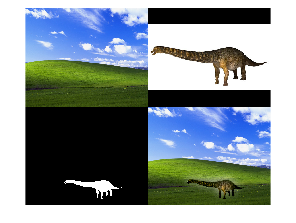


% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result4});




% REPEAT ABOVE FOR IMAGE SET 5
%%%%% your own images
im_bg = im2double(imread('https://laurenslatest.com/wp-content/uploads/2020/08/vanilla-ice-cream-5-copy.jpg'));        % background image
im_obj = im2double(imread('https://www.sidechef.com/recipe/4de2fc5c-a65e-479f-94ef-14aac9e81085.jpg?d=1408x1120'));       % source image

% % Get source region mask (extracted object) from the user
% %  First draw a polygon on the source image for applying the mask

%[poly_x, poly_y] = getPolygonForMask(im_obj);
disp("Copy the values of the vectors poly_x and poly_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of the vectors poly_x and poly_y from the Command Window below and hard code them inside your code for submission via the Grader website.


poly_x = 1.0e+03*[0.6705    0.6204    0.6024    0.5543    0.5002    0.4662    0.4582    0.4582    0.4361    0.4361    0.4201    0.4241    0.4081    0.4161 0.4121    0.3860    0.3780    0.4001    0.4421    0.5102    0.5803    0.6404    0.6785    0.6945    0.7385    0.7946    0.8026    0.8127 0.8647    0.9048    0.9368    0.9609    0.9749    0.9929    1.0049    1.0330    1.0610    1.0570    1.0450    1.0109    0.9909    0.9789 0.9649    0.9468    0.9368    0.9288    0.9128    0.8908    0.8487    0.8086    0.7706    0.7486    0.7345    0.7986    0.7746    0.7285 0.6925    0.6865];       % display x coords of polygon
poly_y = [350.2013  356.2098  364.2212  378.2411  408.2838  448.3407  466.3663  480.3862  506.4232  524.4488  566.5085  580.5284  612.5740  642.6166  666.6508  690.6849  758.7817  792.8300  826.8784  856.9211  878.9523  894.9751  896.9780  870.9410  874.9467  874.9467  858.9239  868.9381  860.9267  856.9211  860.9267  866.9353  832.8869  804.8471  768.7959  752.7731  724.7333  692.6878  660.6422  652.6309  656.6366  626.5939  604.5626  584.5341  578.5256  552.4886  518.4403  480.3862  442.3321  412.2895  388.2553  374.2354  370.2297  368.2269  358.2127  350.2013  350.2013  332.1757];       % display y coords of polygon
% Once you have these coordinates, comment out the call to getPolygonForMask() 
% and hard code the coordinates instead.

objmask = poly2mask(poly_x, poly_y, size(im_obj, 1), size(im_obj, 2));
 
% % Get the bottom center location on the target image by using the function
% % getBottomCenterLoc interactively

%[center_x, bottom_y] = getBottomCenterLoc(im_bg);
disp("Copy the values of center_x and bottom_y from the " + ...
    "Command Window below and hard code them inside your code for " + ...
    "submission via the Grader website.");

Copy the values of center_x and bottom_y from the Command Window below and hard code them inside your code for submission via the Grader website.


center_x = 613.6195;       % display x coord where center of object should be placed
bottom_y = 701.0831;       % display y coord where bottom of object should be placed
% Once you have these coordinates, comment out the call to getBottomCenterLoc()
% and hard code the coordinates instead.

padding = 64;   % You may want to play with this parameter
[im_s, mask_s] = alignSource(im_obj, objmask, im_bg, center_x, bottom_y, padding);
mask_s = im2double(mask_s);

% % Apply your blending method
levels = 6;         % levels in the Laplacian pyramid
result5 = laplacian_blend(im_bg, im_s, mask_s, levels);

ans = 1×3
   900   600     3


ans = 1×3
        1800        1200           3


ans = 1×3
   450   300     3


ans = 1×3
   900   600     3


ans = 1×3
   225   150     3


ans = 1×3
   450   300     3


ans = 1×3
   113    75     3


ans = 1×3
   225   150     3


ans = 1×3
    57    38     3


ans = 1×3
   113    75     3


ans = 1×3
    57    38     3


pyr_size = 1×3
   113    75     3


ans = 1×3
   113    75     3


pyr_size = 1×3
   225   150     3


ans = 1×3
   225   150     3


pyr_size = 1×3
   450   300     3


ans = 1×3
   450   300     3


pyr_size = 1×3
   900   600     3


ans = 1×3
   900   600     3


pyr_size = 1×3
        1800        1200           3


ans = 1×3
   900   600     3


ans = 1×3
        1800        1200           3


ans = 1×3
   450   300     3


ans = 1×3
   900   600     3


ans = 1×3
   225   150     3


ans = 1×3
   450   300     3


ans = 1×3
   113    75     3


ans = 1×3
   225   150     3


ans = 1×3
    57    38     3


ans = 1×3
   113    75     3


ans = 1×3
    57    38     3


pyr_size = 1×3
   113    75     3


ans = 1×3
   113    75     3


pyr_size = 1×3
   225   150     3


ans = 1×3
   225   150     3


pyr_size = 1×3
   450   300     3


ans = 1×3
   450   300     3


pyr_size = 1×3
   900   600     3


ans = 1×3
   900   600     3


pyr_size = 1×3
        1800        1200           3


ans = 1×2
   900   600


ans = 1×2
        1800        1200


ans = 1×2
   450   300


ans = 1×2
   900   600


ans = 1×2
   225   150


ans = 1×2
   450   300


ans = 1×2
   113    75


ans = 1×2
   225   150


ans = 1×2
    57    38


ans = 1×2
   113    75


ans = 1×3
        1800        1200           3


ans = 1×2
        1800        1200


ans = 1×3
   900   600     3


ans = 1×2
   900   600


ans = 1×3
   450   300     3


ans = 1×2
   450   300


ans = 1×3
   225   150     3


ans = 1×2
   225   150


ans = 1×3
   113    75     3


ans = 1×2
   113    75


ans = 1×3
    57    38     3


ans = 1×2
    57    38


imsize = 1×3
        1800        1200           3


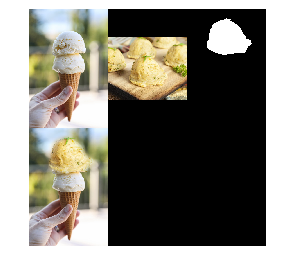


% Display:  target image, source image, mask, then blended result
figure; montage({im_bg, im_obj, mask_s, result5});




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% These are your functions that implement the blending method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



function im_blend = laplacian_blend(im_bg, im_s, mask_s, levels)   
    pyr_L_bg = pyr_laplacian(im_bg, levels);
    pyr_L_fg = pyr_laplacian(im_s, levels);
    pyr_G_mask = pyr_gaussian(mask_s, levels);
    
    pyr = cell([levels, 1]);
    for i = 1:levels
       size(pyr_L_bg{i})
       size(pyr_G_mask{i})
       blur = pyr_L_bg{i}-pyr_L_bg{i}.*pyr_G_mask{i};
       blur = blur+pyr_L_fg{i}.*pyr_G_mask{i};
       
       pyr{i} = blur;
       %pyr_L_fg{i}.*pyr_G_mask{i} + pyr_L_bg{i}.*(1-pyr_G_mask{i});
       
    end
    
    im_blend = pyr_laplacian_collapse(pyr);
end


function pyr_G = pyr_gaussian(im, levels)
% Computes Gaussian pyramid of image im over number of levels
    pyr_G = cell([levels, 1]);      % declare cell array of height "levels", and width 1
    
    pyr_G{1} = im;                  % level 1 is the orignal image
    for i=2:levels
        pyr_G{i} = imresize(imgaussfilt(pyr_G{i-1},2),0.5);
        size(pyr_G{i})
        size(pyr_G{i-1})
    end                             % level i is image at level i-1 filtered with Gaussian(2)
                                    % and then downsampled by factor of 2
end


function pyr_L = pyr_laplacian(im, levels)
% Computes Laplacian pyramid of image im over number of levels
    pyr_G = pyr_gaussian(im, levels);   % first compute the Gaussian pyramid

    pyr_L = cell([levels, 1]);      % declare cell array of height "levels", and width 1
    
    pyr_L{levels} = pyr_G{levels};  % top level of Laplacian pyramid is the same as that of Gaussian pyramid
    for i=(levels-1):-1:1
        size(pyr_G{i+1})
        pyr_size = size(pyr_G{i})
        pyr_L{i} = pyr_G{i} - imresize(pyr_G{i+1}, 'OutputSize', pyr_size(1:2));
                                    % level i of Laplacian is the difference of
                                    % Gaussian level i and upsampled level i+1
                                    % equalizes size by upsampling G{i+1}
    end
end

    
function im = pyr_laplacian_collapse(pyr)
% computes the image from its Laplacian pyramid
    levels = size(pyr, 1);
     
    im = pyr{1};
    imsize = size(im)
    for i = 2:levels
        % the line below would need to account for odd-to-even pixel conversions
        % im = im + imresize(pyr{i}, 2*(i-1));
        im = im + imresize(pyr{i}, imsize(1:2));
    end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Below are complete functions to display Gaussian and
% Laplacian pyramids.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function display_gaussian(pyr)  % code is complete!
% displays the Gaussian pyramid
    figure; montage(pyr);               
end
    
function display_laplacian(pyr) % code is complete!
% displays the Laplacian pyramid
    levels = size(pyr, 1);      
    for i=1:levels-1
        pyr{i} = pyr{i} + 0.5;   % false color all levels except topmost by adding 0.5
    end
    figure; montage(pyr);
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Below are helper functions.  You DO NOT NEED TO MODIFY
% any of the code below.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [im_s2, mask2] = alignSource(im_s, mask, im_t, center_x, bottom_y, padding)
    % Inputs:  source image, mask, target/background image, ...
    % center_x, bottom_y are the coordinates of the bottom center location on the target image
    % padding is the number of extra rows/coumns to include around the
    % object to allow for feathering/blending.

    % Outputs: an aligned source image and also an aligned blending mask.
    
    % find the bounding box of the mask, and enlarge it by the amount of
    % padding
    [y, x] = find(mask);
    y1 = min(y)-1-padding; y2 = max(y)+1+padding; 
    x1 = min(x)-1-padding; x2 = max(x)+1+padding;
    im_s2 = zeros(size(im_t));

    yind = (y1:y2);
    yind2 = yind - max(y) + round(bottom_y);
    xind = (x1:x2);
    xind2 = xind - round(mean(x)) + round(center_x);
    
    % if the padding exceeds the image boundaries,
    % clip to image boundary
    yind(yind > size(im_s, 1)) = size(im_s, 1);
    yind(yind < 1) = 1;
    xind(xind > size(im_s, 2)) = size(im_s, 2);
    xind(xind < 1) = 1;
   
    yind2(yind2 > size(im_t, 1)) = size(im_t, 1);
    yind2(yind2 < 1) = 1;
    xind2(xind2 > size(im_t, 2)) = size(im_t, 2);
    xind2(xind2 < 1) = 1;

    y = y - max(y) + round(bottom_y);
    x = x - round(mean(x)) + round(center_x);
    ind = y + (x-1)*size(im_t, 1);
    mask2 = false(size(im_t, 1), size(im_t, 2));
    mask2(ind) = true;
    
    im_s2(yind2, xind2, :) = im_s(yind, xind, :);    
end
